## The First Question - a

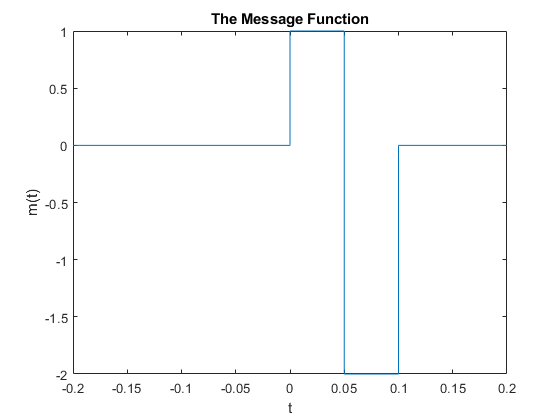

syms t f
x = rectangularPulse((t - 0.025) / 0.05) + (-2) * rectangularPulse((t - 0.075) / 0.05);
fplot(x, [-0.2, 0.2]);
ylabel('m(t)');
xlabel('t');
title('The Message Function');

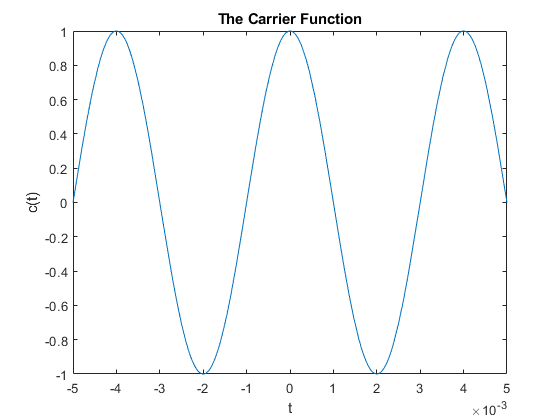

c = cos(2 * pi * 250 * t);
fplot(c, [-0.005, 0.005]);
ylabel('c(t)');
xlabel('t');
title('The Carrier Function');

## The First Question - b - i

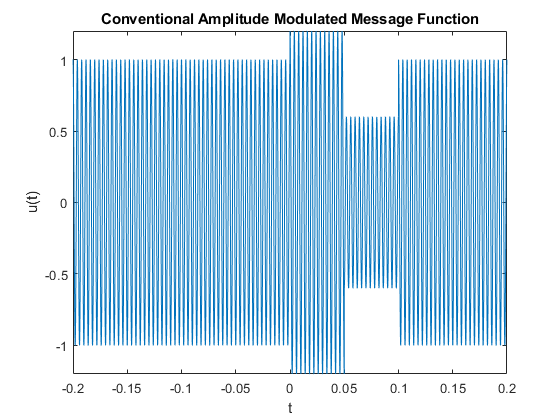

xc = (1 + 0.4 * (x / 2)) * c;
fplot(xc, [-0.2, 0.2]);
ylabel('u(t)');
xlabel('t');
title('Conventional Amplitude Modulated Message Function');

## The First Question - b - ii

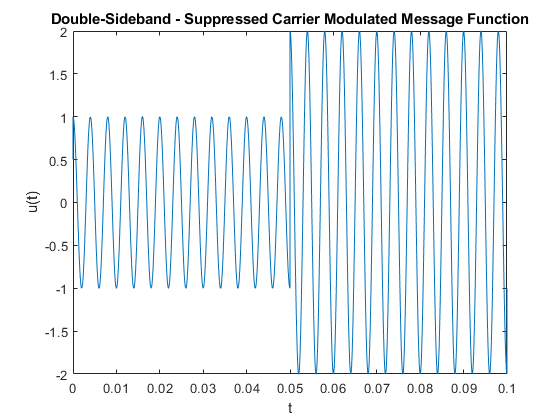

xc = x * c;
fplot(xc, [0, 0.1]);
ylabel('u(t)');
xlabel('t');
title('Double-Sideband - Suppressed Carrier Modulated Message Function');

## The First Question - b - iii

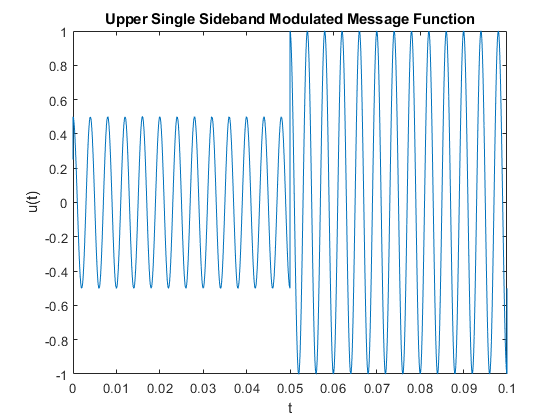

Hilbert_x = ifourier((-1 * j * sign(t) * fourier(x, t)), t);
xc_upper = (x * c - imag(Hilbert_x) * sin(2 * pi * 250 * t)) / 2;
fplot(xc_upper, [0, 0.1]);
ylabel('u(t)');
xlabel('t');
title('Upper Single Sideband Modulated Message Function');

## The First Question - b - iv

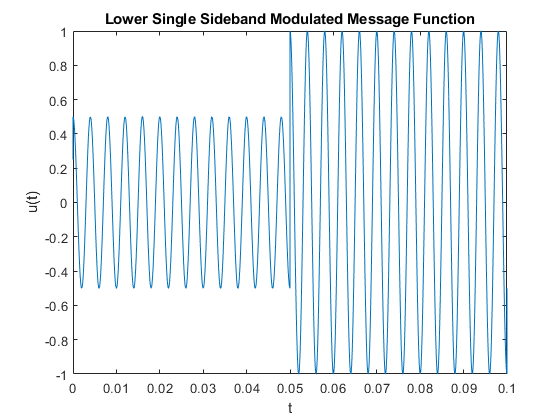

xc_lower = (x * c + imag(Hilbert_x) * sin(2 * pi * 250 * t)) / 2;
fplot(xc_lower, [0, 0.1]);
ylabel('u(t)');
xlabel('t');
title('Lower Single Sideband Modulated Message Function');

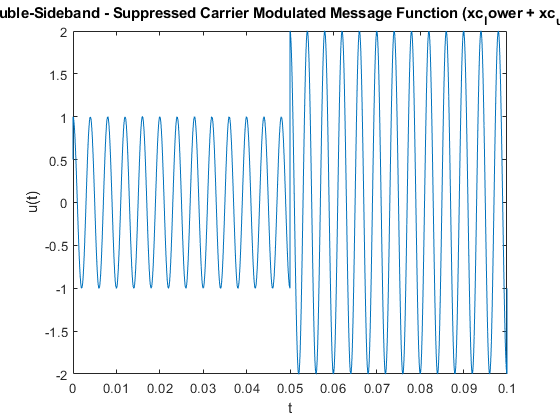

fplot(xc_lower + xc_upper, [0, 0.1])
ylabel('u(t)');
xlabel('t');
title('Double-Sideband - Suppressed Carrier Modulated Message Function (xc_lower + xc_upper)');